# Adaptive Tracking of Maneuvering Targets with Managed Radar

This example shows how to use radar resource management to efficiently track multiple maneuvering targets. Tracking maneuvering targets requires the radar to revisit the targets more frequently than tracking non-maneuvering targets. An interacting multiple model (IMM) filter estimates when the target is maneuvering. This estimate helps to manage the radar revisit time and therefore enhances the tracking. This example uses the Radar Toolbox™ for the radar model and Sensor Fusion and Tracking Toolbox™ for the tracking.

## Introduction

Multifunction radars can search for targets, confirm new tracks, and revisit tracks to update the state. To perform these functions, a multifunction radar is often managed by a resource manager that creates radar tasks for search, confirmation, and tracking. These tasks are scheduled according to priority and time so that, at each time step, the multifunction radar can point its beam in a desired direction. The [Search and Track Scheduling for Multifunction Phased Array Radar](docid:radar_ug#example-ex19431218) example shows a multifunction phased-array radar managed with a resource manager.

In this example, we extend the [Search and Track Scheduling for Multifunction Phased Array Radar](docid:radar_ug#example-ex19431218) example to the case of multiple maneuvering targets. There are two conflicting requirements for a radar used to track maneuvering targets:

- The number of targets and their initial location are typically not known in advance. Therefore, the radar must continuously search the area of interest to find the targets. Also, the radar needs to detect and establish a track on each target as soon as it enters the radar coverage area.

- The time period of target maneuvering is unknown in advance. If it is known that targets are not maneuvering, the radar can revisit the targets infrequently. However, since the maneuver start and end times are unknown, the radar must revisit each track frequently enough to be able to recognize when the maneuver starts and ends.

The radar must balance between providing enough beams centered on the tracked targets and leaving enough time to search for new targets. One approach is to simply define a revisit rate on each tracked target regardless of its maneuvering status and leave the remaining time for new target searching. This radar management scheme is sometimes referred to as *Active Tracking *[1]. As more targets become tracked, the radar can either perform fewer search tasks or it can track each target less frequently. Clearly, if the number of targets is large, the radar can be overwhelmed.

Active tracking treats all the tracks in the same way, which makes it a *mode*-based resource management algorithm. A more sophisticated way to manage the radar is based on the properties of each track. For example, use track properties such as the size of state uncertainty covariance, whether the track is maneuvering, and how fast it is moving towards an asset the radar site protects. When such properties are used, the radar resource management is referred to as *Adaptive Tracking *[1]. 

In this example, you compare the results of Active Tracking and Adaptive Tracking when the radar adapts based on estimated track maneuver.

## Define Scenario and Radar Model

You define a scenario and a radar with an update rate of 20 Hz, which means that the radar has 20 beams per second allocated for either search, confirmation, or tracking. You load the benchmark trajectories used in the [Benchmark Trajectories for Multi-Object Tracking](docid:fusion_ug#mw_61c422f8-396d-424c-b316-bb96117bbd85) example. There are six benchmark trajectories and you define a trajectory for each one. The six platforms in the figure follow non-maneuvering legs interspersed with maneuvering legs. You can view the trajectories in the figure.

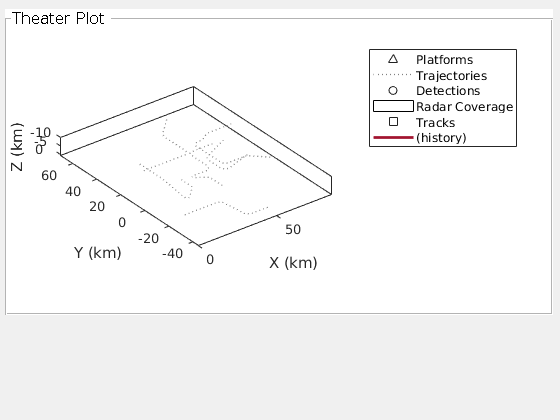

% Create scenario
updateRate = 20;
scenario = trackingScenario('UpdateRate',updateRate);
% Add the benchmark trajectories
load('BenchmarkTrajectories.mat','-mat');
platform(scenario,'Trajectory',v1Trajectory);
platform(scenario,'Trajectory',v2Trajectory);
platform(scenario,'Trajectory',v3Trajectory);
platform(scenario,'Trajectory',v4Trajectory);
platform(scenario,'Trajectory',v5Trajectory);
platform(scenario,'Trajectory',v6Trajectory);

% Create visualization
f = figure;
mp = uipanel('Parent',f,'Title','Theater Plot','FontSize',12,...
    'BackgroundColor','white','Position',[.01 .25 .98 .73]);
tax = axes(mp,'ZDir','reverse');

% Visualize scenario
thp = theaterPlot('Parent',tax,'AxesUnits',["km","km","km"],'XLimits',[0 85000],'YLimits',[-45000 70000],'ZLimits',[-10000 1000]);
plp = platformPlotter(thp, 'DisplayName', 'Platforms');
pap = trajectoryPlotter(thp, 'DisplayName', 'Trajectories', 'LineWidth', 1);
dtp = detectionPlotter(thp, 'DisplayName', 'Detections');
cvp = coveragePlotter(thp, 'DisplayName', 'Radar Coverage');
trp = trackPlotter(thp, 'DisplayName', 'Tracks', 'ConnectHistory', 'on', 'ColorizeHistory', 'on');
numPlatforms = numel(scenario.Platforms);
trajectoryPositions = cell(1,numPlatforms);
for i = 1:numPlatforms
    trajectoryPositions{i} = lookupPose(scenario.Platforms{i}.Trajectory,(0:0.1:185));
end
plotTrajectory(pap, trajectoryPositions);
view(tax,3)

A probabilistic radar model is defined using the `radarDataGenerator` System object™. Setting the '`ScanMode'` property of this object to `'Custom'` allows the resource manager to control the radar look angle. This enables scheduling of the radar for searching, confirming, and tracking targets. The radar is mounted on a new platform in the scenario.

radar = radarDataGenerator(1, ...
    'ScanMode', 'Custom', ...
    'UpdateRate', updateRate, ...
    'MountingLocation', [0 0 -15], ...
    'AzimuthResolution', 1.5, ...
    'ElevationResolution', 10, ...
    'HasElevation', true, ...
    'DetectionCoordinates', 'Sensor spherical');
platform(scenario,'Position',[0 0 0],'Sensors',radar);

## **Define Tracker**

After the radar detects objects, it feeds the detections to a tracker, which performs several operations. The tracker maintains a list of tracks that are estimates of target states in the area of interest. If a detection cannot be assigned to any track already maintained by the tracker, the tracker initiates a new track. In most cases, whether the new track represents a true target or false target is unclear. At first, a track is created with a tentative status. If enough detections are obtained, the track becomes confirmed. Similarly, if no detections are assigned to a track, the track is coasted (predicted without correction). If the track has a few missed updates, the tracker deletes the track.

In this example, you use a tracker that associates the detections to the tracks using a global nearest neighbor (GNN) algorithm. To track the maneuvering targets, you define a `FilterInitializationFcn` function that initializes an IMM filter. The `initMPARIMM` function uses two motion models: a constant-velocity model and a constant-turn rate model. The [`trackingIMM`](docid:fusion_ref#mw_62f9c34a-52dc-46da-9b05-20bec8172d68) filter is responsible for estimating the probability of each model, which you can access from its `ModelProbabilities` property. In this example, you classify a target as maneuvering when the probability of the constant-turn rate model is higher than 0.6.

tracker = trackerGNN('FilterInitializationFcn',@initMPARIMM,...
    'ConfirmationThreshold',[2 3], 'DeletionThreshold',[5 5],...
    'HasDetectableTrackIDsInput',true,'AssignmentThreshold',150,...
    'MaxNumTracks',10,'MaxNumSensors',1);
posSelector = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0];

## Radar Resource Management

This section only briefly outlines the radar resource management. For more details, see the [Search and Track Scheduling for Multifunction Phased Array Radar](docid:radar_ug#example-ex19431218) example.

**Search Tasks**

In this example, you assign search tasks deterministically. A raster scan is used to cover the desired airspace. The azimuth scanning limits are set to [-90 60] degrees and the elevation limits to [-9.9 0] degrees. If no other tasks exist, the radar scans the space one angular cell at a time. The size of an angular cell is determined by the radar's `AzimuthResolution` and `ElevationResolution` properties. Negative elevation angles mean that the radar points the beam from the horizon up.

AzimuthLimits = [-90 60];
ElevationLimits = [-9.9 0];
azscanspan   = diff(AzimuthLimits);
numazscan    = floor(azscanspan/radar.AzimuthResolution)+1;
azscanangles = linspace(AzimuthLimits(1),AzimuthLimits(2),numazscan)+radar.MountingAngles(1);
elscanspan   = diff(ElevationLimits);
numelscan    = floor(elscanspan/radar.ElevationResolution)+1;
elscanangles = linspace(ElevationLimits(1),ElevationLimits(2),numelscan)+radar.MountingAngles(2);
[elscangrid,azscangrid] = meshgrid(elscanangles,azscanangles);  
scanangles   = [azscangrid(:) elscangrid(:)].';
searchq = struct('JobType','Search','BeamDirection',num2cell(scanangles,1),...
    'Priority',1000,'WaveformIndex',1);
current_search_idx = 1;

**Track Tasks**

Unlike search tasks, track tasks cannot be planned in advance. Instead, the resource manager creates confirmation and tracking tasks based on the changing scenario. The main difference in this example from the [Search and Track Scheduling for Multifunction Phased Array Radar](docid:radar_ug#example-ex71697352) example is that the `JobType` for each track task can be either `"TrackNonManeuvering"` or `"TrackManeuvering"`. The distinction between the two types of tracking tasks enables you to schedule tasks for each type of track at different revisit rates, making it an adaptive tracking algorithm. Similar to search tasks, tracking tasks are also managed in a job queue.

trackq = repmat(struct('JobType',[],'BeamDirection',[],'Priority',3000,'WaveformIndex',[],...
    'Time',[],'Range',[],'TrackID',[]), 10, 1);
num_trackq_items = 0;

Group search and tracking queues together in a structure for easier reference in the simulation loop.

jobq.SearchQueue  = searchq;
jobq.SearchIndex  = current_search_idx;
jobq.TrackQueue   = trackq;
jobq.NumTrackJobs = num_trackq_items;
jobq.PositionSelector = posSelector;
% Keep a reset state of jobq
resetJobQ = jobq;

**Task Scheduling**

In this example, for simplicity, the multifunction radar executes only one type of job within a small time period, often referred to as a dwell, but can switch tasks at the beginning of each dwell. For each dwell, the radar looks at all tasks that are due for execution and picks a confirmation or track task if its time to run has come. Otherwise, the radar picks a search task. To control the time to run tasks, you set the `managerPreferences` structure defined below. The highest revisit rate, which is equal to the radar update rate, is given to the `confirm` task to guarantee that a confirmation beam follows every new tentative track that exists. Similarly, you can control the revisit rate for non-maneuvering and maneuvering targets. In this case, you choose the values of 0.8 Hz and 4 Hz for non-maneuvering and maneuvering targets, respectively. Since there are 6 targets, the resource manager will use $6\cdot0.8\approx5$ updates per second on tracking targets if all of them are not maneuvering. Given the radar update rate is 20 Hz, the radar manager will perform approximately one target update in every four updates. Thus, the radar will be spending about 75% of the time in the search mode and 25% of the time in the tracking mode. When new tracks are initialized and when the tracker considers that the targets are maneuvering, the resource manager allocates more tracking beams at the expense of search beams.

The Analyze Results section shows the results of other options.

managerPreferences = struct(...
    'Type', {"Search","Confirm","TrackNonManeuvering","TrackManeuvering"}, ...
    'RevisitRate', {0, updateRate, 0.8, 4}, ...
    'Priority', {1000, 3000, 1500, 2500});

## Run the Scenario

During the simulation, the radar beam is depicted by blue or purple colors representing search and track-related beams, respectively. You can also see the distribution of tasks between search and specific tracks for the last second of simulation using the Resource Allocation in the Last Second panel at the bottom of the figure. In the Theater Plot part of the figure, you can see the history of each track and compare it to the trajectory.

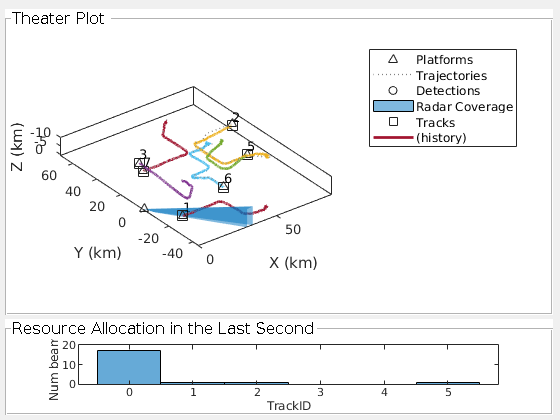

% Create a radar resource allocation display
rp = uipanel('Parent',f,'Title','Resource Allocation in the Last Second','FontSize',12,...
    'BackgroundColor','white','Position',[.01 0.01 0.98 0.23]);
rax = axes(rp);

% Run the scenario
allocationType = helperAdaptiveTrackingSim(scenario, thp, rax, tracker, resetJobQ, managerPreferences);

## **Analyze Results**

Analyze the radar task load and its division between search, confirmation, and tracking jobs. The graph shows that most of the time the radar allocates about 75% search jobs and 25% tracking jobs, which is as expected when the targets are not maneuvering. When the targets are maneuvering, the resource manager adapts to allocate more tracking jobs. When more tracks are maneuvering at the same time, there are more tracking jobs, as seen near the 700th time step. The confirmation jobs occupy very little of the radar time because the tracker is configured to confirm tracks after two detection associations in three attempts. Therefore, the confirmation or rejection of tentative tracks is swift.

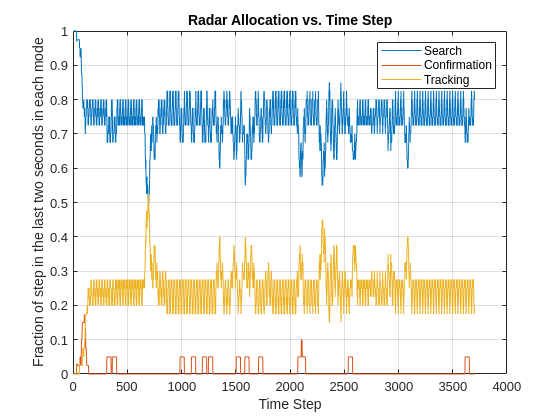

numSteps = numel(allocationType);
allocationSummary = zeros(3,numSteps);
for i = 1:numSteps
    for jobType = 1:3
        allocationSummary(jobType,i) = sum(allocationType(1,max(1,i-2*updateRate+1):i)==jobType)/min(i-1,2*updateRate);
    end
end
figure;
plot(1:numSteps,allocationSummary(:,1:numSteps))
title('Radar Allocation vs. Time Step');
xlabel('Time Step');
ylabel('Fraction of step in the last two seconds in each mode');
legend('Search','Confirmation','Tracking');
grid on

Compare this result with the result of Active Tracking at 0.8 Hz track revisit rate. The following figures show the tracking results and radar allocation graph for the Active Tracking case. The tracking results show that some tracks were lost and broken, but the radar resource allocation graph shows a similar 75% search and 25% tracking task division as in the case of the Adaptive Tracking. You can obtain these results by executing the code sample below.

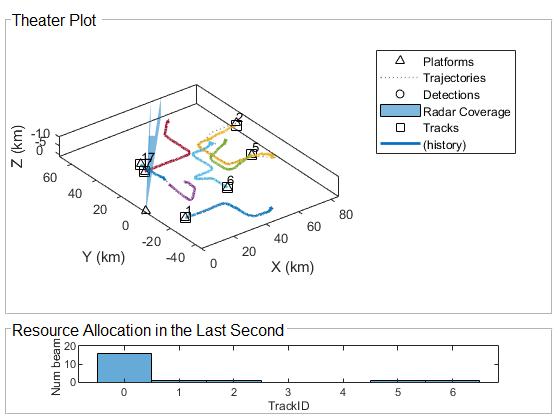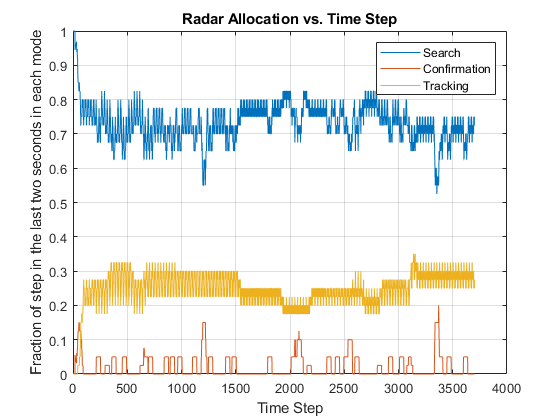

Clearly, a higher tracking revisit rate is needed for Active Tracking. The following two graphs show that increasing the track revisit rate to 2 Hz improves the tracking of maneuvering targets. However, the cost is that the radar dedicates more than 50% of its time to tracking tasks even when the tracks are not maneuvering. If the number of targets were greater, the radar would become overwhelmed.

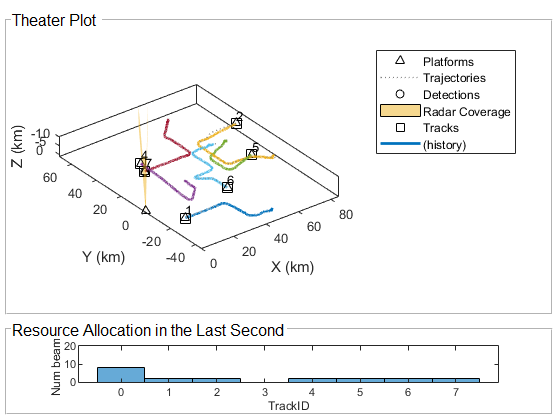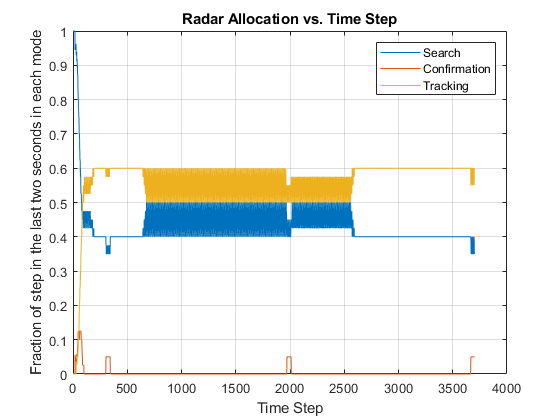

The previous results show that it is enough to revisit the maneuvering targets at a rate of 2 Hz. However, can Adaptive Tracking be used to lower the revisit rate of non-maneuvering targets beyond 0.8 Hz? The following graphs present results for 0.6 Hz and 4 Hz for non-maneuvering and maneuvering targets, respectively. With this setting, the radar resource allocation allows for 80%-85% of the time in search mode, leaving the radar with capacity to search and track even more targets.

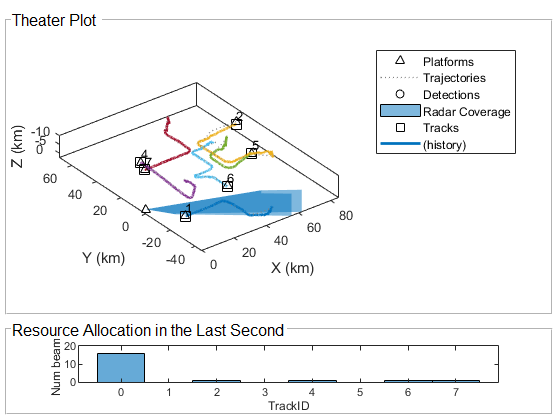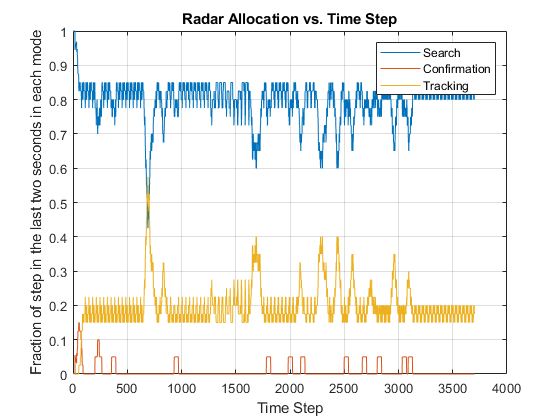

## **Summary**

This example shows how to use the combination of tracking and radar resource management to adapt the revisit rate for maneuvering tracks. Adaptive tracking allows you to select revisit rate that is appropriate for each target type and maneuvering status. As a result, the radar becomes more efficient and can track a larger number of maneuvering targets.

**References**

[1] Charlish, Alexander, Folker Hoffmann, Christoph Degen, and Isabel Schlangen. “The Development From Adaptive to Cognitive Radar Resource Management.” *IEEE Aerospace and Electronic Systems Magazine* 35, no. 6 (June 1, 2020): 8–19. [https://doi.org/10.1109/MAES.2019.2957847](https://doi.org/10.1109/MAES.2019.2957847).

## Supporting Functions

`getCurrentRadarTask`

Returns the radar task that is used for pointing the radar beam.

type('getCurrentRadarTask.m')

function [currentjob,jobq] = getCurrentRadarTask(jobq,current_time)

searchq   = jobq.SearchQueue;
trackq    = jobq.TrackQueue;
searchidx = jobq.SearchIndex;
num_trackq_items = jobq.NumTrackJobs;

% Update search queue index
searchqidx = mod(searchidx-1,numel(searchq))+1;

% Find the track job that is due and has the highest priority
readyidx = find([trackq(1:num_trackq_items).Time]<=current_time);
[~,maxpidx] = max([trackq(readyidx).Priority]);
taskqidx = readyidx(maxpidx);

% If the track job found has a higher priority, use that as the current job
% and increase the next search job priority since it gets postponed.
% Otherwise, the next search job due is the current job.
if ~isempty(taskqidx) % && trackq(taskqidx).Priority >= searchq(searchqidx).Priority
    currentjob = trackq(taskqidx);
    for m = taskqidx+1:num_trackq_items
        trackq(m-1) = trackq(m);
    end
    num_trackq_items = num_trackq_items-1;
    searchq(searchqidx).Priority = searchq(searchqidx).Priority+100;
else

`helperAdaptiveRadarSim`

Runs the simulation

type('helperAdaptiveTrackingSim.m')

function allocationType = helperAdaptiveTrackingSim(scenario, thp, rax, tracker, resetJobQ, managerPreferences)
% Initialize variables
radar = scenario.Platforms{end}.Sensors{1};
updateRate = radar.UpdateRate;
resourceAllocation = nan(1,updateRate);
h = histogram(rax,resourceAllocation,'BinMethod','integers');
xlabel(h.Parent,'TrackID')
ylabel(h.Parent,'Num beams');
numSteps = updateRate * 185;
allocationType = nan(1,numSteps);
currentStep = 1;
restart(scenario);
reset(tracker);
% Return to a reset state of jobq
jobq = resetJobQ;

% Plotters and axes
plp = thp.Plotters(1);
dtp = thp.Plotters(3);
cvp = thp.Plotters(4);
trp = thp.Plotters(5);

ax = gca;
colors = ax.ColorOrder;

% For repeatable results, set the random seed and revert it when done
s = rng(2020);
oc = onCleanup(@() rng(s));

% Main loop
tracks = {};

while advance(scenario)
    time = scenario.SimulationTime;
    
    % Update ground truth display
    poses = platformPoses(scenario);
    plotPlatform(plp, reshape([poses.Po

`initMPARIMM`

Initializes the IMM filter used by the tracker.

type('initMPARIMM.m')

function imm = initMPARIMM(detection)

cvekf = initcvekf(detection);
cvekf.StateCovariance(2,2) = 1e6;
cvekf.StateCovariance(4,4) = 1e6;
cvekf.StateCovariance(6,6) = 1e6;

ctekf = initctekf(detection);
ctekf.StateCovariance(2,2) = 1e6;
ctekf.StateCovariance(4,4) = 1e6;
ctekf.StateCovariance(7,7) = 1e6;
ctekf.ProcessNoise(3,3) = 1e6; % Large noise for unknown angular acceleration

imm = trackingIMM('TrackingFilters', {cvekf;ctekf}, 'TransitionProbabilities', [0.99, 0.99]);


`manageResources`

Manages the job queue and creates new tasks based on the tracking results.

type('manageResource.m')

function jobq = manageResource(detections,jobq,tracker,tracks,current_job,current_time,managerPreferences)

trackq           = jobq.TrackQueue;
num_trackq_items = jobq.NumTrackJobs;
if ~isempty(detections)
    detection = detections{1};
else
    detection = [];
end

% Execute current job
switch current_job.JobType
    case 'Search'
        % For search job, if there is a detection, establish tentative
        % track and schedule a confirmation job
        if ~isempty(detection)           
            % A search task can still find a track we already have. Define
            % a confirmation task only if it's a tentative track. There
            % could be more than one if there are false alarms. Create
            % confirm jobs for tentative tracks created at this update.

            numTentative = numel(tracks.tentativeTracks);
            for i = 1:numTentative
                if tracks.tentativeTracks(i).Age == 1 && tracks.tentativeTracks(i).IsCoasted == 0
                    tra

*Copyright 2020-2024 The MathWorks, Inc.*